plotBiomassOverTime(celtab.model);

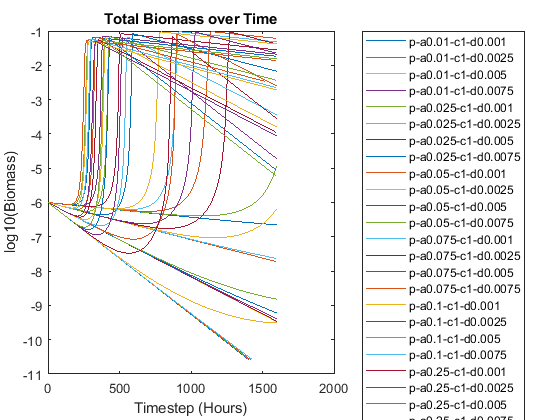

dat0 = celtab(celtab.cellulose_init == 1,:);
plotBiomassOverTime(dat0.model);

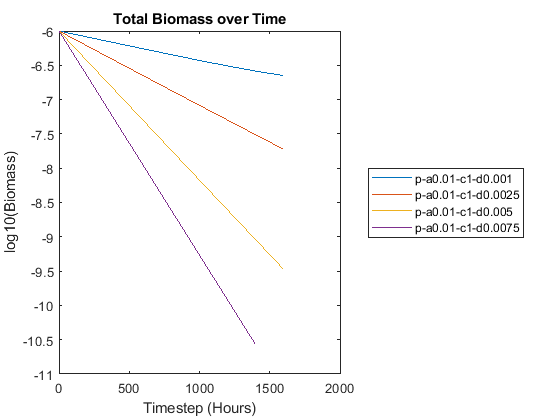

dat = dat0(dat0.alpha == 0.01,:);
plotBiomassOverTime(dat.model);

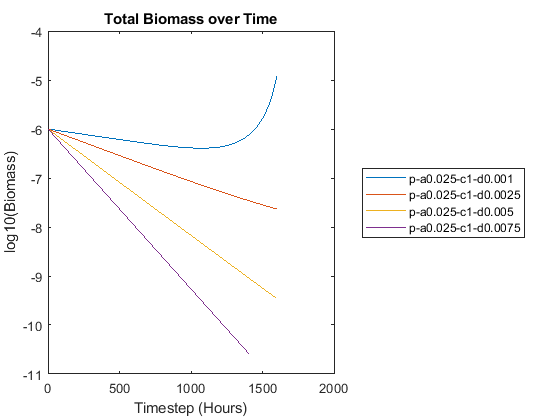

dat = dat0(dat0.alpha == 0.025,:);
plotBiomassOverTime(dat.model);

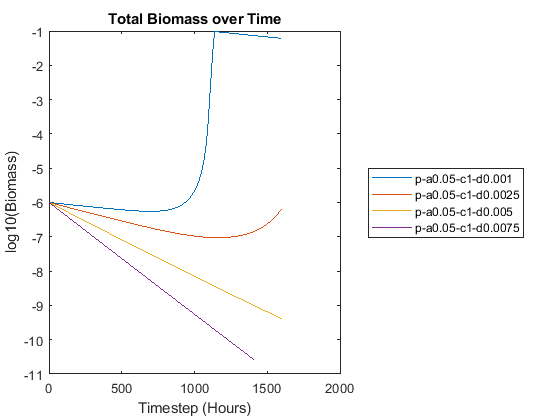

dat = dat0(dat0.alpha == 0.05,:);
plotBiomassOverTime(dat.model);

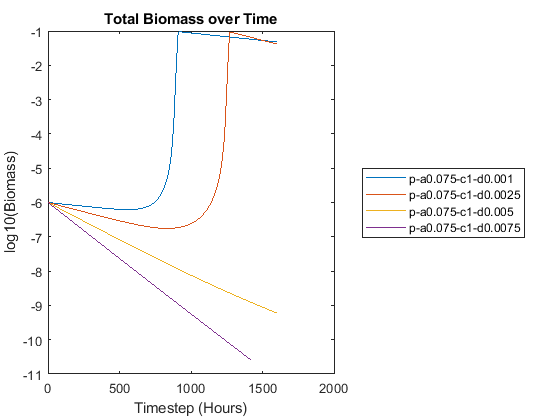

dat = dat0(dat0.alpha == 0.075,:);
plotBiomassOverTime(dat.model);

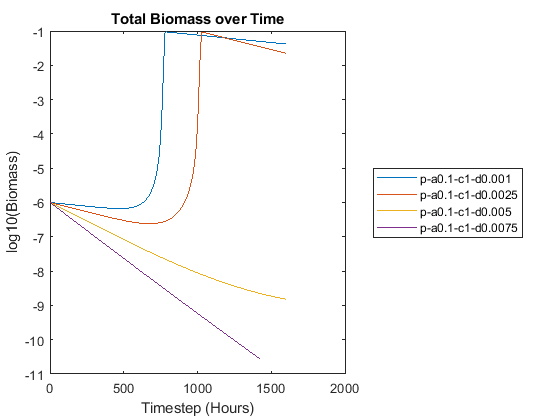

dat = dat0(dat0.alpha == 0.1,:);
plotBiomassOverTime(dat.model);

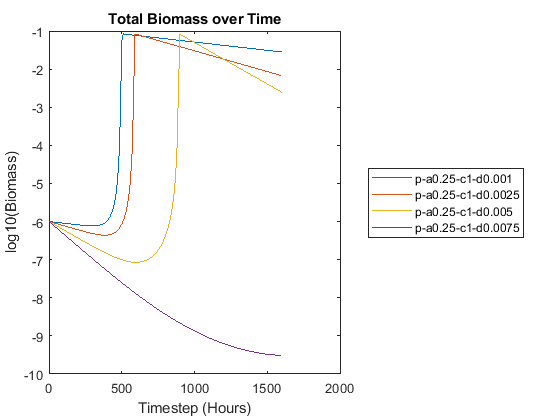

dat = dat0(dat0.alpha == 0.25,:);
plotBiomassOverTime(dat.model);


dat = celtab(celtab.deathrate == 0.0025,:); %Deathrate = 2%/hr
row = dat(dat.alpha == 0.1 & dat.cellulose_init == 1, :);

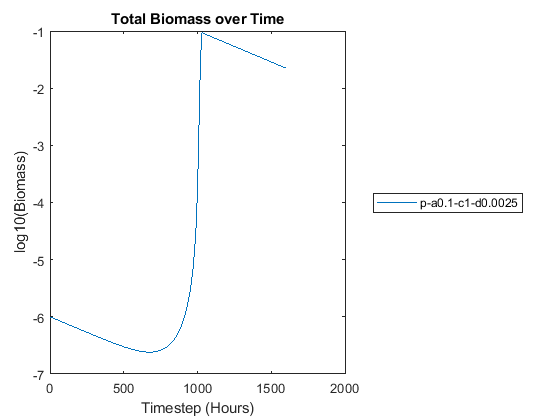

plotBiomassOverTime(row.model);

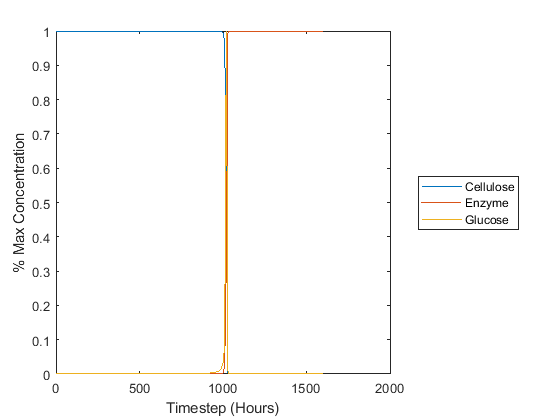

plotAllTimecourses(row.model{1},'pctmax');

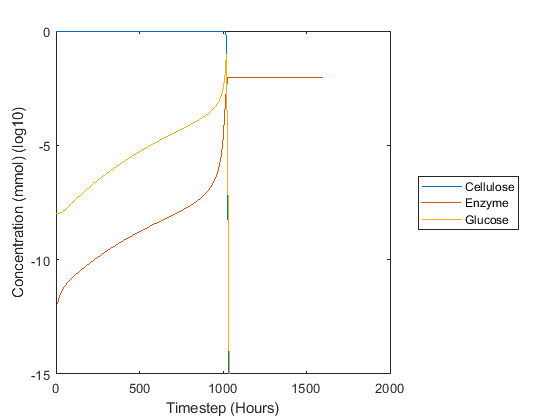

plotAllTimecourses(row.model{1},'log10');
ylim([-15 0]);

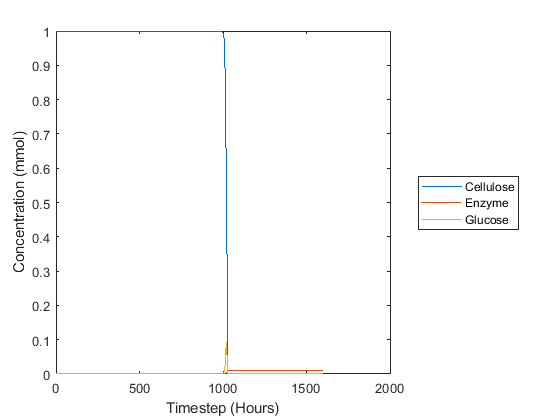

plotAllTimecourses(row.model{1},'');

%rebuild this record with more timepoints
v = row.model{1}.v;
v.lograte = 1;
model_default = load('C:\sync\biomes\models\iJO1366 (1).mat'); %model with metabolite names normalized
model_default = model_default.iJO1366;
m = buildEcoliModel(v,model_default,'tesmodel','p');
t = table();
t.cellulose_init = v.initcellulose;
t.alpha = v.alpha;
t.model = {m};
t = refreshCelOptDataTable(t);

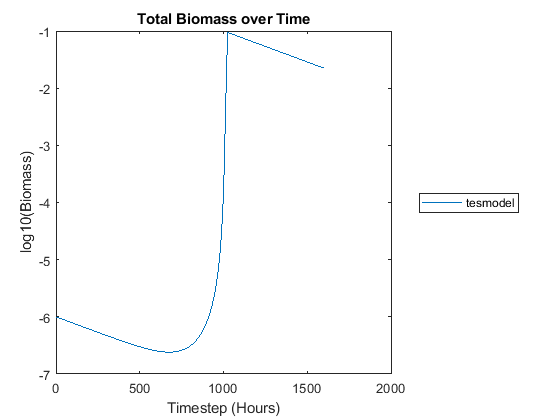

plotBiomassOverTime(t.model);

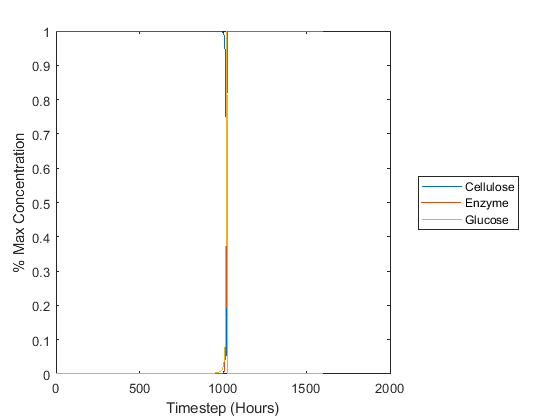

plotAllTimecourses(t.model{1},'pctmax');

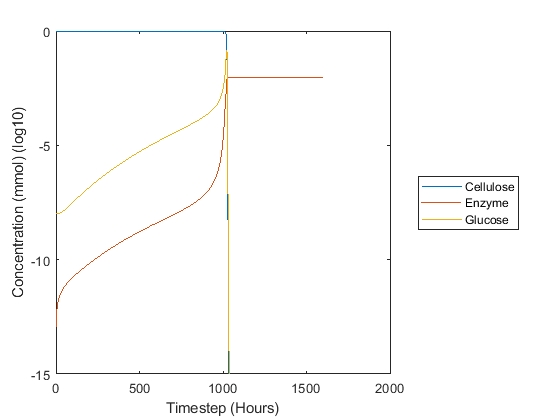

plotAllTimecourses(t.model{1},'log10');
ylim([-15 0]);

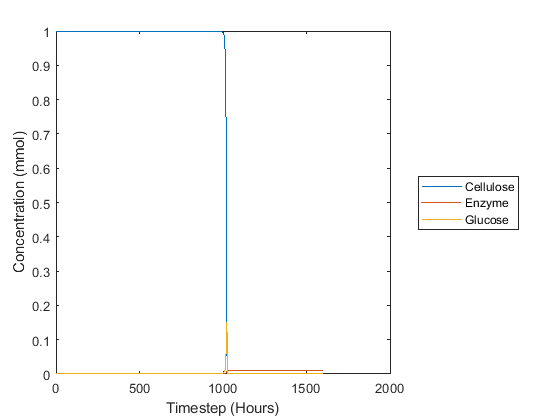

plotAllTimecourses(t.model{1},'');

dat = celtab(celtab.deathrate == 0.0025,:); %Deathrate = 2%/hr
row = dat(dat.alpha == 0.1 & dat.cellulose_init == 0.5, :);

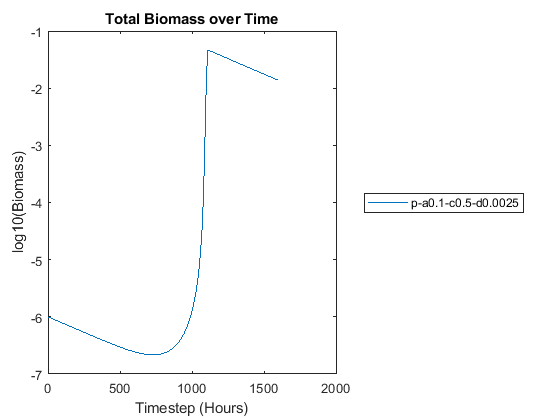

plotBiomassOverTime(row.model);

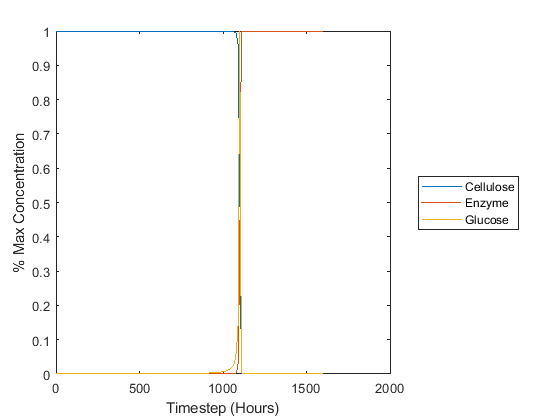

plotAllTimecourses(row.model{1},'pctmax');

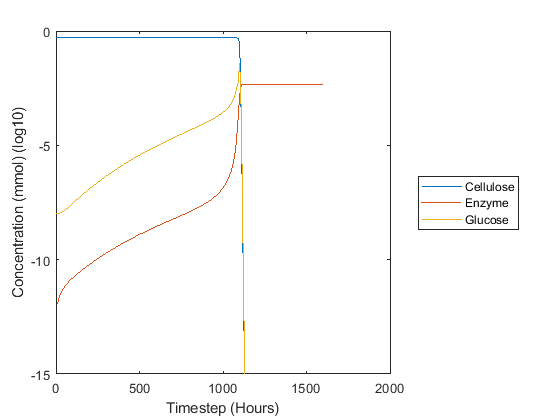

plotAllTimecourses(row.model{1},'log10');
ylim([-15 0]);

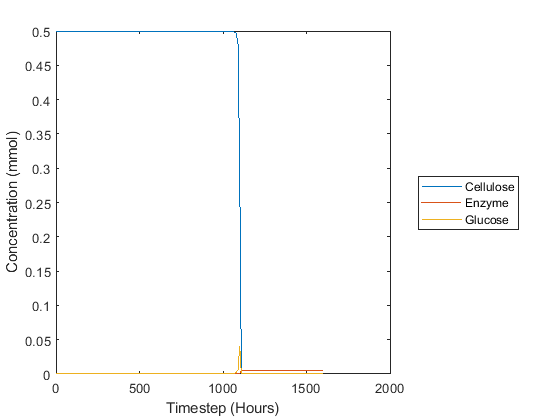

plotAllTimecourses(row.model{1},'');

%rebuild this record with more timepoints
v = row.model{1}.v;
v.lograte = 1;
model_default = load('C:\sync\biomes\models\iJO1366 (1).mat'); %model with metabolite names normalized
model_default = model_default.iJO1366;
m = buildEcoliModel(v,model_default,'tesmodel','p');
t = table();
t.cellulose_init = v.initcellulose;
t.alpha = v.alpha;
t.model = {m};
t = refreshCelOptDataTable(t);

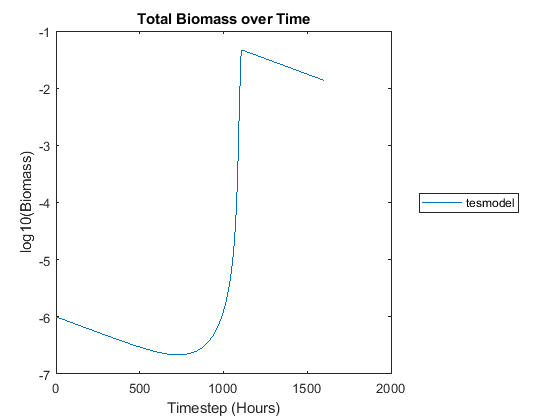

plotBiomassOverTime(t.model);

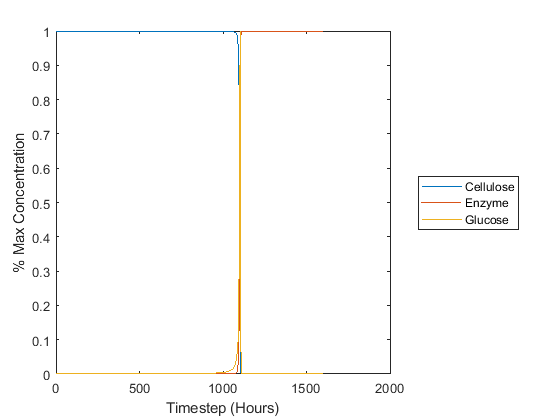

plotAllTimecourses(t.model{1},'pctmax');

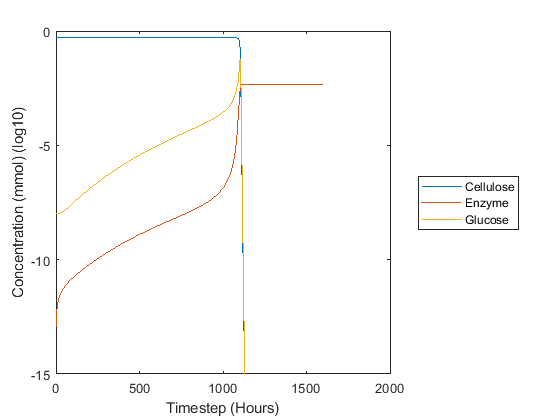

plotAllTimecourses(t.model{1},'log10');
ylim([-15 0]);

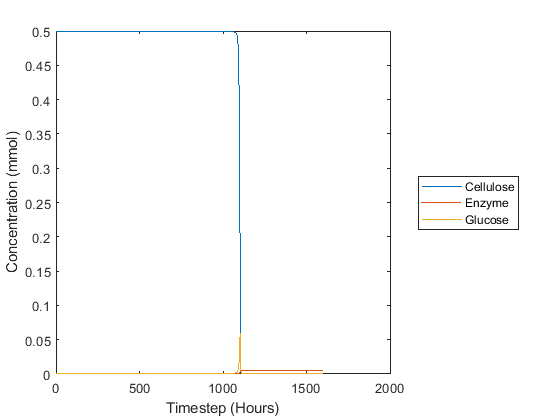

plotAllTimecourses(t.model{1},'');